# PROCESS CONTROL ASSIGNMENT 2

Name: NSENGUMUKIZA IRENE

MATRIC N0.: G2303789D

# LQR applied to aircraft

**(i) Design \quad 3 LQR \quad controllers for a fixed**$ $\gamma=0.01$ \quad and \quad $\rho=0.1,10,100$.$

gamma = 1e-2; 
rhos = [1e-1, 10, 1e2];
figure;
hold on;
for rho = rhos
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gamma*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
[K, P, poles] = lqr(A, B, Q, R, N);
GO = ss(A, B, K, 0);
[GainMargin, PhaseMargin, GainCrossOverFreq, PhaseCrossOverFreq] = margin(GO);
sprintf('rho = %d and gamma = %d', rho, gamma)
disp('------------------------------------')
disp(PhaseMargin)
bode(GO)
end

ans = 'rho = 1.000000e-01 and gamma = 1.000000e-02'

------------------------------------


   66.6468



ans = 'rho = 10 and gamma = 1.000000e-02'

------------------------------------


   70.2300



ans = 'rho = 100 and gamma = 1.000000e-02'

------------------------------------


   74.9383



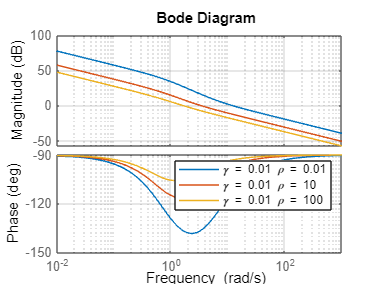

grid on;
hold off;
legend('\gamma = 0.01 \rho = 0.01', '\gamma = 0.01 \rho = 10', '\gamma = 0.01 \rho = 100')

**(ii). Design 3 LQR controllers for a fixed **$$\rho=0.01$ and $\gamma=0.01,0.1,1$$

rho = 1e-2; % Example values for gamma
gamma = [1e-2, 0.1, 1]; % Example values for rho
figure;
hold on;
for gam = gamma
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gam*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
[K2, P2, poles2] = lqr(A, B, Q, R, N);
sprintf('rho = %d and gamma = %d', rho, gam)
disp('------------------------------------')
GO = ss(A, B, K2, 0);
[GainMargin, PhaseMargin, GainCrossOverFreq, PhaseCrossOverFreq] = margin(GO);
disp('Phase margin: ')
disp(PhaseMargin)
disp('------------------------------------')
bode(GO);
% step(GO);
end

ans = 'rho = 1.000000e-02 and gamma = 1.000000e-02'

------------------------------------


Phase margin: 


   65.7652



------------------------------------


ans = 'rho = 1.000000e-02 and gamma = 1.000000e-01'

------------------------------------


Phase margin: 


   74.3118



------------------------------------


ans = 'rho = 1.000000e-02 and gamma = 1'

------------------------------------


Phase margin: 


   72.7870



------------------------------------


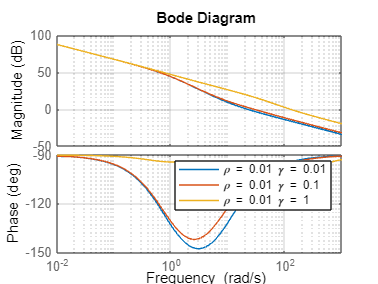

grid on;
hold off;
legend('\rho = 0.01 \gamma = 0.01', '\rho = 0.01 \gamma = 0.1', '\rho = 0.01 \gamma = 1')

**(iii) Determine the phase margins for the LQR controllers designed in Part 2(a)(i)and (ii).**

for each controller I used to compute phase margin at design point since I was using loop to iterate over them, the easiest way was to calculate phase margin of each controller at that point of designing.

**For the controllers designed in part 1**


$$\rho = 0.1 \quad \gamma = 0.01 \quad Phase -margin= 66.6468 \degree \\
\rho = 10 \quad \gamma = 0.01 \quad Phase -margin= 70.230 \degree \\
\rho = 100 \quad \gamma = 0.01 \quad Phase -margin= 74.9383 \degree \\
$$


**Effect of increasing **$$\rho$$

Increasing $$\rho$$ With $$\gamma$$ held constant at 0.01 leads to an increase in the phase margin. This indicates that increasing the weight on the state error relative to the control effort can make the system more robust to phase changes, as a higher phase margin indicates a larger buffer before the system reaches instability.

**For controllers designed in part 2**


$$\rho = 0.01 \quad \gamma = 0.01 \quad Phase -margin= 65.7652 \degree \\
\rho = 0.01 \quad \gamma = 0.1 \quad Phase -margin= 74.3118 \degree \\
\rho = 0.01 \quad \gamma = 1 \quad Phase -margin= 72.7870 \degree \\$$


**Effect of increasing **$$\gamma$$

Initially increasing $$\gamma$$ from 0.01 to 0.1 increases the phase margin, but further increasing $$\gamma$$ to 1 results in a slight decrease in the phase margin. This suggests that there might be an optimal range for 

$$\gamma$$ that maximizes the phase margin. This behavior is typical as tuning parameters may have non-linear effects on system stability metrics.

## Nyquist plot

`(i) Select `$$ Q = I_{2 \times 2}, R = 1, \rho = 0.1, \gamma = 1$$`. Plot the Nyquist plot of the loop transfer function`

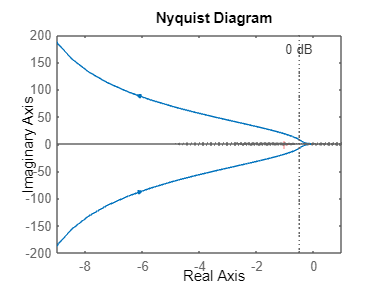

gamma = 1; % Example values for gamma
rho = 1e-1; % Example values for rho

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
G = [1 0 0; 0, gamma*1, 0];
H = [0; 0];
Q = G' * G;
R = H'* H + rho;
N = G'* H;
K = lqr(A, B, Q, R, N);
GO = ss(A, B, K, 0);
figure;
nyquist(GO);
grid on;

`(ii) Under state feedback u = -Kx, the closed-loop dynamics are given by`


$$\dot{x} = (A - BK)x$$


`and the closed-loop poles are the eigenvalues of `$A - BK$`. compute a state feedback gain matrix `$K$` that assigns these poles to any locations. closed loop poles `$p = -1, -2, -3$**.**

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];

% Define the desired closed-loop poles
p = [-1, -2, -3];

% Compute the state feedback gain matrix K using the place function
K = place(A, B, p)

K =    -0.0060   -0.0065   -0.8975


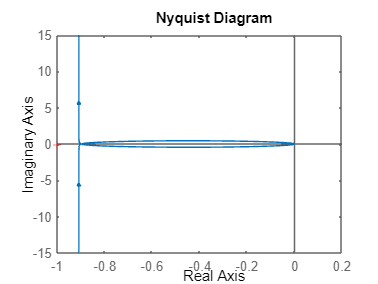

GO = ss(A, B, K, 0);
figure;
nyquist(GO);

**(iii) Compare the Nyquist plots obtained in (i) and (ii) in terms of whether these plots enter within a circle of radius 1 centered at -1. What can you conclude about the robustness of the 2 design methods against multiplicative uncertainty?**

The Nyquist plots for two control design methods were examined for robustness against multiplicative uncertainty by observing their behavior around a circle of radius 1 centered at -1 in the complex plane. Both plots avoided encircling the critical point, indicative of stable closed-loop systems. The first design method's Nyquist plot shows a conservative approach with a significant margin from the critical stability boundary. In contrast, the second method's plot, though more expansive, similarly does not intersect with the defined circle, suggesting an adequate stability margin.

Neither design's Nyquist plot enters the critical circle, pointing towards an inherent robustness to uncertainties that could perturb the system's poles within this region. While this suggests that both methods offer stable control strategies resistant to certain levels of uncertainty, a full assessment of robustness would require additional analysis, such as evaluating gain and phase margins, transient responses, and overall system performance objectives.

## Step Response

(i) Plot on the same graph, the step responses to roll angle setpoint command of  r = 1  rad for the 3 LQR state feedback controllers designed in Part 2(a) (i) for $\rho$ = 0.1, 10, 100  and $\gamma = 0.01$

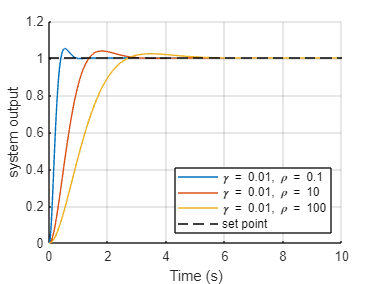

A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
gamma = 1e-2; % Fixed value for gamma
rhos = [1e-1, 1e1, 1e2]; % Iterating over these values for rho
G = [1 0 0; 0, gamma, 0];
H = [0; 0];
Q = G' * G;

% Define the reference set point
r = [1; 0; 0]; % Reference for the first state

% Simulation parameters
dt = 0.01; % Time step (s)
T = 10; % Total simulation time (s)
time = 0:dt:T; % Time vector

figure;
hold on;

% Iterate over the different values of rho
for idx = 1:length(rhos)
    R = rhos(idx); % Use the current rho value for R

    % Solve for the LQR gain matrix K
    [K, ~, ~] = lqr(A, B, Q, R);
    % Initial conditions
    x = zeros(3,1); % Initialize state

    % Preallocate state history for plotting
    x_history = zeros(3, length(time));

    % Closed-loop simulation
    for i = 1:length(time)
        % Control law with reference tracking
        u = -K*(x - r);

        % System dynamics
        x_dot = A*x + B*u;

        % Euler integration for state update
        x = x + x_dot * dt;

        % Store state history
        x_history(:, i) = x;
    end

    % Plotting for the current rho value
    plot(time, x_history(1,:), 'DisplayName', ['\gamma = ', num2str(gamma), ', \rho = ', num2str(rhos(idx))]);
end

% Plot reference line
plot(time, r(1)*ones(size(time)), 'k--', 'DisplayName', 'set point');

% Enhance plot
% title('Open-loop gain for several values of \rho and \gamma = 0.01');
xlabel('Time (s)');
ylabel('system output');
legend('show');
legend('Location', 'southeast');
grid on;
hold off;

`(ii) Plot on the same graph, the step responses to roll angle setpoint command of r=1 rad for the 3 LQR state feedback controllers designed in Part 2(a) (ii) for `$\gamma$` = 0.01, 0.1, 1.`

% Define system matrices
A = [0 1 0; 0 -0.875 -20; 0 0 -50];
B = [0; 0; 50];
rho = 1e-2; 
gamma = [1e-2, 1e-1, 1]; 
R = rho; 
r = [1; 0; 0];

% Simulation parameters
dt = 0.01; % Time step (s)
T = 6; % Total simulation time (s)
time = 0:dt:T; % Time vector

% Preallocate figure for plots
figure;
hold on;

% Iterate over the different values of rho
for idx = 1:length(gamma)
    G = [1 0 0; 0, gamma(idx), 0];
    Q = G' * G;
    % Solve for the LQR gain matrix K
    [K, ~, ~] = lqr(A, B, Q, R);

    fprintf("%d : K: ", idx);
    disp(K)
    disp('________________________________________')
    % Initial conditions
    x = zeros(3,1); % Initialize state

    % Preallocate state history for plotting
    x_history = zeros(3, length(time));

    % Closed-loop simulation
    for i = 1:length(time)
        % Control law with reference tracking
        u = -K*(x - r);

        % System dynamics
        x_dot = A*x + B*u;

        % Euler integration for state update
        x = x + x_dot * dt;

        % Store state history
        x_history(:, i) = x;
    end

    % Plotting for the current rho value
    plot(time, x_history(1,:), 'DisplayName', ['\gamma = ', num2str(gamma(idx)), ', \rho = ', num2str(R)]);
end

1 : K: 

  -10.0000   -1.1264    0.3788



________________________________________


2 : K: 

  -10.0000   -1.5184    0.4882



________________________________________


3 : K: 

  -10.0000  -10.0186    2.0025



________________________________________


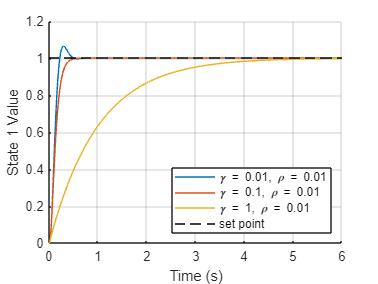


% Plot reference line
plot(time, r(1)*ones(size(time)), 'k--', 'DisplayName', 'set point');
legend('Location', 'southeast');
% Enhance plot
% title('State 1 Trajectories with LQR Control and Reference Tracking for Different \rho');
xlabel('Time (s)');
ylabel('State 1 Value');
legend('show');
grid on;
hold off;

**(iii) Compare the effect of the step responses (speed and overshoot) for variations in **$\rho$**  and **$\gamma$

**For varying **$$\rho$$

**Low** 

$$\rho$$ (0.01): The response quickly rises to the setpoint with some initial overshoot and oscillations, indicating a potentially more aggressive control action with less weight on control effort (since $$\rho$$ is in the denominator of the control weight in the LQR cost function). 

**Medium**

$$\rho$$ (10): The response is slower, with no overshoot, showing a more conservative control action where both state errors and control effort are more balanced.

**High **

$$\rho$$ (100): The response is the slowest, with the least aggressive control action, indicating a high weight on minimizing control effort compared to state errors.

**For fixed **$$\rho$$

**Low** $$\gamma$$ (0.01): Similar to the low 

$$\rho$$ case, the system responds quickly and with an initial overshoot, indicating an aggressive control action that prioritizes state error over control effort.

**Medium** 

$$\gamma$$ (0.1): The response is slower and with no overshoot, suggesting a balance between state error and control effort.

**High **

$$\gamma$$ (1): The response is very slow and the least aggressive, prioritizing control effort significantly over state error minimization.

**Comparative Analysis**

Speed of Response

 Lower values of $$\rho$ $ and $$\gamma$$ leads to faster system responses. This is because a lower value in the LQR cost function denominator implies less emphasis on the control effort, allowing the controller to act more aggressively to minimize state errors. 

Overshoot

Lower values of $$\rho$$ and $$\gamma$$ results in more overshoot, which is typical for more aggressive control strategies. Higher values tend to suppress overshoot, indicating a more cautious approach to control action.

Stability and Robustness

While not directly observable from these plots, systems with higher values of 

$$\rho$$ and $$\gamma$$ are likely to be more robust to disturbances and model uncertainties since they apply control more gently, avoiding sharp reactions that could be destabilizing in the presence of real-world uncertainties.

Control Effort

A higher value of $$\rho$$ and $$\gamma$$ implies a controller that puts more emphasis on reducing control effort, which can be important for energy savings or when dealing with actuator limitations.

## Set-Point Tracking

`(i) Repeat 2(c)(i) but now include the pre-compensated gain e to achieve zero offset to step roll command r`

% Define system matrices
R = [0.1, 10, 100];
gamma = 0.01

gamma = 0.0100

A = [0 1 0; 0 -0.875 20; 0 0 -50];
B = [0; 0; 50];
figure;
for j = 1:length(R)
C = [1 0 0; 0, gamma, 0];
Q = C' * C;

Rj = R(j)
% Compute the LQR gain matrix K
[K, ~, ~] = lqr(A, B, Q, Rj);

r = 1; 

% Simulation parameters
dt = 0.01; % Time step (s)
T = 10; % Total simulation time (s)
time = 0:dt:T; % Time vector
x_history = zeros(3, length(time));
% Preallocate figure for plots
x = zeros(3,1); % Initialize state to match the system dimension

for i = 1:length(time)
    % Control law with reference tracking and pre-compensatory gain
    u = -K * (x - r);
    % System dynamics
    Ccl = [1 0 0];
    Bcl = [1; 0; 0];
    e = -1 / (Ccl*inv(A - B*K)*Bcl);
    % x_dot = A * x + B * u + Bcl'*r*e;
    x_dot = (A - B*K)*x + Bcl*r*e;
    % Euler integration for state update
    x = x + x_dot * dt;
    
    % % Store state history
    x_history(:, i) = x;
end
% plot(time, x_history(1,:));
plot(time, x_history(1,:), 'DisplayName', ['\gamma = ', num2str(gamma), ', \rho = ', num2str(R(j))]);
hold on
end

Rj = 0.1000

Rj = 10

Rj = 100

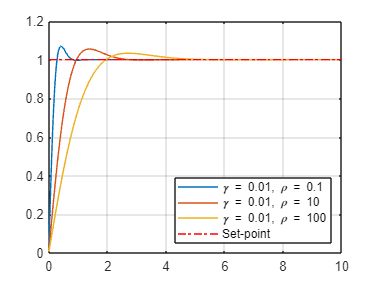

plot(time, repmat([1], 1, size(x_history(1,:), 2)), 'r-.', ...
    'DisplayName','Set-point');
grid on
legend('show');
legend('Location', 'southeast');
hold off

`(i) Repeat 2(c)(ii) but now include the pre-compensated gain e to achieve zero offset to step roll command r`

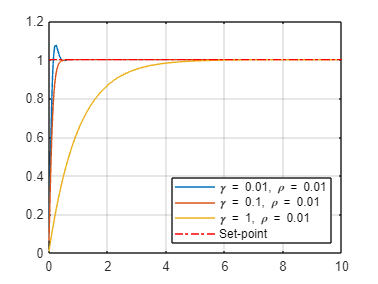

% Define system matrices
R = 0.01;
gamma = [0.01, 0.1, 1];
A = [0 1 0; 0 -0.875 20; 0 0 -50];
B = [0; 0; 50];
figure;
for j = 1:length(gamma)
C = [1 0 0; 0, gamma(j), 0];
Q = C' * C;
% Compute the LQR gain matrix K
[K, ~, ~] = lqr(A, B, Q, R);

r = 1; 

% Simulation parameters
dt = 0.01; % Time step (s)
T = 10; % Total simulation time (s)
time = 0:dt:T; % Time vector
x_history = zeros(3, length(time));
% Preallocate figure for plots
x = zeros(3,1); % Initialize state to match the system dimension

for i = 1:length(time)
    % Control law with reference tracking and pre-compensatory gain
    u = -K * (x - r);
    % System dynamics
    Ccl = [1 0 0];
    Bcl = [1; 0; 0];
    e = -1 / (Ccl*inv(A - B*K)*Bcl);
    % x_dot = A * x + B * u + Bcl'*r*e;
    x_dot = (A - B*K)*x + Bcl*r*e;
    % Euler integration for state update
    x = x + x_dot * dt;
    
    % % Store state history
    x_history(:, i) = x;
end
% plot(time, x_history(1,:));
plot(time, x_history(1,:), 'DisplayName', ['\gamma = ', num2str(gamma(j)), ', \rho = ', num2str(R)]);
hold on
end
plot(time, repmat([1], 1, size(x_history(1,:), 2)), 'r-.', ...
    'DisplayName','Set-point');
grid on
% legend('Response', 'Set-point')
hold off
legend('show');
legend('Location', 'southeast');

## Quadcopter Dynamics

A = zeros(12,12);
g = 9.81;
m = 1;
I_y = 0.11;
I_x = I_y;
I_z = 0.04;
A(2,9) = g;
A(4,7) = g;
for i = 1:2:size(A, 1)
    A(i,i+1) = 1;
end

B = zeros(12,4);
B(6, 1) = 1/m;
B(8, 2) = 1/I_x;
B(10, 3) = 1/I_y;
B(12, 4) = 1/I_z;

C = zeros(6, 12);
for i = 1:size(C, 1)
    C(i, (2*i)-1) = 1;
end
D = zeros(6,4);
A

A =          0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    9.8100         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    9.8100         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0        

B

B =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000         0         0         0
         0         0         0         0
         0    9.0909         0         0
         0         0         0         0
         0         0    9.0909         0


C

C =      1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0


D

D =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


**(i)  Compute the poles and zeros of System**

sys = ss(A, B, C, D);
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


MIMO_Gf = C*inv((s*eye(12)-A))*B + D

MIMO_Gf =
 
  From input 1 to output...
   1:  0
 
   2:  0
 
                     1
   3:  -----------------------------
       s^2 - 2.234e-16 s - 1.941e-31
 
   4:  0
 
   5:  0
 
   6:  0
 
  From input 2 to output...
   1:  0
 
                                   89.18
   2:  -------------------------------------------------------------
       s^4 - 4.842e-16 s^3 - 3.004e-16 s^2 - 8.643e-17 s + 7.246e-17
 
   3:  0
 
                   9.091
   4:  -----------------------------
       s^2 - 7.744e-18 s + 1.477e-17
 
   5:  0
 
   6:  0
 
  From input 3 to output...
                                   89.18
   1:  -------------------------------------------------------------
       s^4 - 1.561e-16 s^3 - 9.376e-16 s^2 + 4.556e-16 s - 3.633e-17
 
   2:  0
 
   3:  0
 
   4:  0
 
                   9.091
   5:  -----------------------------
       s^2 - 2.234e-16 s - 1.941e-31
 
   6:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
               


disp('Poles: ')

Poles: 


poles_found = pole(MIMO_Gf)

poles_found = 1.0e-04 *

   0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.6524 + 0.6524i
  -0.6524 - 0.6524i
   0.6524 + 0.6524i
   0.6524 - 0.6524i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
  -0.7765 + 0.0000i
   0.0002 + 0.7764i



disp('Transmission zeros: ')

Transmission zeros: 


zeros_found = tzero(MIMO_Gf)


zeros_found =

  0×1 empty double column vector



`(ii) Use MIMO state feedback to design the state feedback gain `$u = -Kx + r$`  and plot the step response for the closed loop with initial state `$x(0) = 0_{12\times1}$`, and the reference input with X=5m, Y=7m, Z=10m and `$\Psi$` = 1 rad. It is desired to achieve a rise time of about 2 s and a settling time of 3.5 s.`

`To design the state feedback gain, `$$K$$`, we can employ methods such as pole placement or the Linear Quadratic Regulator (LQR). For the sake of simplicity and illustrative purposes, we opt for pole placement in this instance. The poles are selected based on the desired rise time and settling time of the system, as these are critical parameters that define the transient response characteristics.`

`The rise time, which we aim to be approximately 2 seconds, is influenced predominantly by the system's dominant poles. For an underdamped second-order system, the natural frequency, `$$\omega_n$$`, can be estimated using the following rule of thumb:`


$$\omega_n \approx \frac{1.8}{\text{rise time}}$$


`Similarly, the settling time—desired to be about 3.5 seconds—is related to the location of the poles with respect to the imaginary axis. The poles should be positioned according to the equation below to achieve a settling time that corresponds to within `$2\%$` of the final value:`


$$\text{Pole Location} \approx \frac{\ln(0.05)}{\text{settling time}}$$


`By appropriately placing the poles in the complex plane, we can engineer a system response that meets the specified rise time and settling time requirements.`


$$\text{desired poles} = [-1.8/2 -1.8/3.5 -1.8/3.5 -1/2 -1/2 -1/3.5 -1/3.5 -0.5/2 -0.5/2 -0.5/3.5 -0.5/3.5 -0.2/2]$$


desired_poles = [-1.8/2 -1.8/3.5 -1.8/3.5 -1/2 -1/2 -1/3.5 -1/3.5 -0.5/2 -0.5/2 -0.5/3.5 -0.5/3.5 -0.2/2];
K = place(A, B, desired_poles)

K =     0.1853    2.6614   -0.0522   -0.7338    0.0994    0.6860  -28.1651  -31.3049  102.4868  114.3898   -0.0029   -0.0064
    0.0000    0.0004    0.0002    0.0025   -0.0000   -0.0000    0.1109    0.1933    0.0159    0.0175    0.0000    0.0000
    0.0000    0.0008    0.0000    0.0005    0.0000    0.0000    0.0178    0.0195    0.0500    0.1265    0.0000    0.0000
    0.0010    0.0126    0.0009    0.0066   -0.0001   -0.0003    0.0969    0.0084    0.4499    0.4789    0.0057    0.0317


%% MISSING SOLUTION 

`(iii) Design the LQR state feedback control `$u = -Kx + r$` to achieve rise time of about 2 s and a settling time of 3.5 s by minimizing a quadratic cost function `

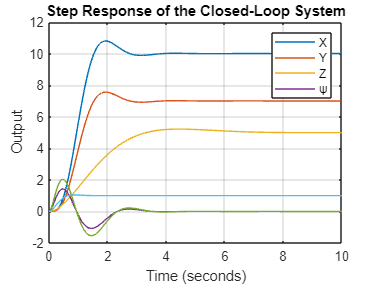

Q = C' * C;  
R = eye(4); 

% Calculate the optimal gain matrix K
[K, ~, ~] = lqr(A, B, Q, R);
A_cl = A - B * K;
sys_cl = ss(A_cl, B, C, D);
% Initial state and step input
x0 = zeros(12, 1);  % initial state
r = [5; 7; 10; 1];  % reference input for X, Y, Z, ψ

% Simulate the step response
t = 0:0.01:10;  % Time vector
[y, t, x] = lsim(sys_cl, repmat(r', length(t), 1), t, x0);

% Plotting the step response
figure;
plot(t, y);
title('Step Response of the Closed-Loop System');
xlabel('Time (seconds)');
ylabel('Output');
legend('X', 'Y', 'Z', 'ψ');
grid on;

`(iv) To eliminate the attitude error, we shall implement integral feedback to the LQR in Part 2e(iii). LQR or any state feedback control with integral feedback is shown below. Use the augmented model (2.7)-(2.8) to improve the performance of Part 2e(iii).`

## $\( H_{\infty} \)$ Design

nums = {12 -0.05; 0.1 [1 0]};
dens = {[0.2 1] [0.1 1]; [0.3 1] [0.7 -1]};
Gnom = tf(nums,dens);

**(i) Compute the zeros and poles of **$G_{nom}(s)$**.**

disp('Poles: ')

Poles: 


pole(Gnom)

ans =    -5.0000
   -3.3333
  -10.0000
    1.4286



disp('Zeros: ')

Zeros: 


tzero(Gnom)

ans =   -10.0017
    0.0004
   -3.3340


**(ii) Express the transfer function matrix of Gnom(s) into state  space description.**

sysss = ss(Gnom)

sysss =
 
  A = 
           x1      x2      x3      x4
   x1      -5       0       0       0
   x2       0  -3.333       0       0
   x3       0       0     -10       0
   x4       0       0       0   1.429
 
  B = 
        u1   u2
   x1    8    0
   x2  0.5    0
   x3    0  0.5
   x4    0    2
 
  C = 
           x1      x2      x3      x4
   y1     7.5       0      -1       0
   y2       0  0.6667       0    1.02
 
  D = 
          u1     u2
   y1      0      0
   y2      0  1.429
 
Continuous-time state-space model.


**(iii) Is the state space description in Part 3(a)(ii) a minimum  realization**

Ctrb = ctrb(sysss.A, sysss.B);
% Check the rank of the controllability matrix
rank_Ctrb = rank(Ctrb)

rank_Ctrb = 4


% Determine if the system is controllable
if rank_Ctrb == size(sysss.A, 1)
    disp('The system is controllable.');
else
    disp('The system is not controllable.');
end

The system is controllable.



Obsv_mat = obsv(sysss);
rank_obs = rank(Obsv_mat)

rank_obs = 4


% Determine if the system is controllable
if rank_obs == size(sysss.A, 1)
    disp('The system is observable.');
else
    disp('The system is not observable.');
end

The system is observable.


**conclusion**

This is minimal realization since it is controllable and observable

**(iv) Plot the singular values of Gnom(s) and determine the  maximum singular value over all frequencies.**

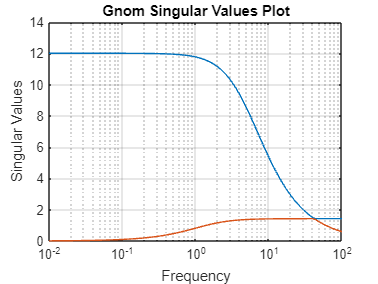

f_range = logspace(-2, 2, 100);  % Frequency range
sv = sigma(Gnom, f_range);
figure;
semilogx(f_range, sv);
xlabel('Frequency');
ylabel('Singular Values');
title('Gnom Singular Values Plot');
grid on

% maximum singular value for all frequencies
max_sv = max(sv);
fprintf('Max singular value: %.2f\n', max_sv);

Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 11.99
Max singular value: 11.99
Max singular value: 11.99
Max singular value: 11.99
Max singular value: 11.99
Max singular value: 11.98
Max singular value: 11.98
Max singular value: 11.98
Max singular

## Mixed Sensitivity Problem

s = tf('s');
Gnom = [12/(0.2*s+1) -0.05/(0.1*s + 1); 0.1/(0.3*s+1) (5*s)/(0.7*s-1)]

Gnom =
 
  From input 1 to output...
          12
   1:  ---------
       0.2 s + 1
 
          0.1
   2:  ---------
       0.3 s + 1
 
  From input 2 to output...
         -0.05
   1:  ---------
       0.1 s + 1
 
          5 s
   2:  ---------
       0.7 s - 1
 
Continuous-time transfer function.
Model Properties



% weights
W1 = (s+10)/(2*s+0.3);
W2 = []; 
W3 = (s+10)/(0.05*s+20);

**(i) Design a Hꝏ mixed sensitivity optimal controller**

% H-infinity optimal controller
[Kh,cl,gamma,info] = mixsyn(Gnom,W1,W2,W3);
Kh

Kh =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1       -0.15    2.08e-22  -7.402e-25  -1.469e-20   1.067e-23  -4.849e-22  -7.832e-25   2.666e-21
   x2   -3.84e-15       -0.15  -7.199e-17   1.954e-14   1.184e-14  -1.938e-13  -8.006e-16   2.255e-12
   x3  -1.624e-17   1.038e-15        -400  -7.338e-14         480  -2.422e-15         -64   1.332e-14
   x4     0.03289      0.1742     0.01575      -82.28      -0.119       8.619    0.009797         -41
   x5       5.535     0.04567       102.2      0.1563      -142.4    -0.03075        17.9      0.1196
   x6      0.3459    0.002854       6.389    0.009766      -8.588      -3.335       1.119    0.007477
   x7   3.666e-05    0.000147   1.738e-05      0.3506   -0.000128    -0.03714         -10      -0.224
   x8   -0.001236       0.099  -0.0002098      -4.107   -0.005858     -0.5252    0.001027       0.891
 
  B = 
               u1          u2
   x1           2  -2.933e-21

cl

cl =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16
   x1        -0.15           0           0           0         -15           0           2           0           0           0           0           0           0           0           0           0
   x2            0       -0.15           0           0           0      -1.333           0      -5.102   -0.001047     -0.0042  -0.0004966      -10.02    0.003656       1.061  -0.0002942       6.399
   x3            0           0        -400           0         480           0         -64           0           0           0           0           0           0           0           0           0
   x4            0           0           0        -400           0       42.67           0       163.3     0.03352      0.1344     0.01589       320.5      -0.117      -33.95    0.009413    

gamma

gamma = 33.3336

(ii) Analyse the sensitivity and complementary sensitivity functions  with the aid of the following commands. Does the minimum  singular value of $S^{-1}$  lie below the magnitude response of W1 and  the maximum singular value of T lie below the magnitude  response of 1/W3 ?

looptransfer = loopsens(Gnom,Kh)

looptransfer = struct with fields:
        Si: [2×2 ss]
        Ti: [2×2 ss]
        Li: [2×2 ss]
        So: [2×2 ss]
        To: [2×2 ss]
        Lo: [2×2 ss]
       PSi: [2×2 ss]
       CSo: [2×2 ss]
     Poles: [12×1 double]
    Stable: 1


Lo = looptransfer.Lo;
To = looptransfer.To

To =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1           -5           0           0           0      -5.535    -0.04567      -102.2     -0.1563       137.4     0.03075       -17.9     -0.1196
   x2            0      -3.333           0           0     -0.3459   -0.002854      -6.389   -0.009766       8.588    0.001922      -1.119   -0.007477
   x3            0           0         -10           0  -3.666e-05   -0.000147  -1.738e-05     -0.3506    0.000128     0.03714   -1.03e-05       0.224
   x4            0           0           0       1.429  -0.0002933   -0.001176  -0.0001391      -2.805    0.001024      0.2971  -8.236e-05       1.792
   x5           15  -1.956e-21          -2  -7.483e-21       -0.15   2.141e-22  -1.189e-26  -3.362e-24   5.304e-24  -2.041e-21  -3.517e-25  -6.719e-21
   x6   -7.109e-18       1.333   9.479e-19       5.102   -0.001047     -0.1542  

So = looptransfer.So

So =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1           -5           0           0           0      -5.535    -0.04567      -102.2     -0.1563       137.4     0.03075       -17.9     -0.1196
   x2            0      -3.333           0           0     -0.3459   -0.002854      -6.389   -0.009766       8.588    0.001922      -1.119   -0.007477
   x3            0           0         -10           0  -3.666e-05   -0.000147  -1.738e-05     -0.3506    0.000128     0.03714   -1.03e-05       0.224
   x4            0           0           0       1.429  -0.0002933   -0.001176  -0.0001391      -2.805    0.001024      0.2971  -8.236e-05       1.792
   x5           15  -1.956e-21          -2  -7.483e-21       -0.15   2.141e-22  -1.189e-26  -3.362e-24   5.304e-24  -2.041e-21  -3.517e-25  -6.719e-21
   x6   -7.109e-18       1.333   9.479e-19       5.102   -0.001047     -0.1542  

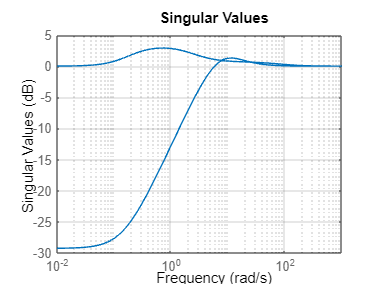

I = eye(size(Lo));
figure(2)
omega = logspace(-1,3,100);
sigma(So), grid on

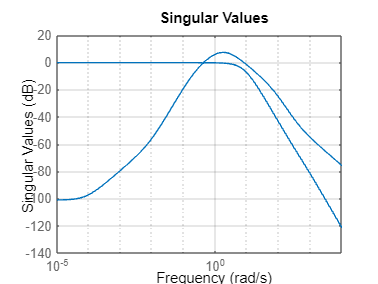

sigma(To), grid on


% minimum singular values of 1/So
min_sv = min(sigma(inv(So),omega))

min_sv =     0.9145    0.9026    0.8897    0.8762    0.8621    0.8478    0.8333    0.8191    0.8053    0.7921    0.7798    0.7684    0.7582    0.7490    0.7411    0.7342    0.7285    0.7240    0.7204    0.7179    0.7163    0.7157    0.7161    0.7174    0.7196    0.7228    0.7269    0.7320    0.7380    0.7450    0.7529    0.7616    0.7711    0.7813    0.7918    0.8027    0.8137    0.8246    0.8351    0.8453    0.8548    0.8637    0.8718    0.8792    0.8857    0.8916    0.8966    0.8944    0.8781    0.8672


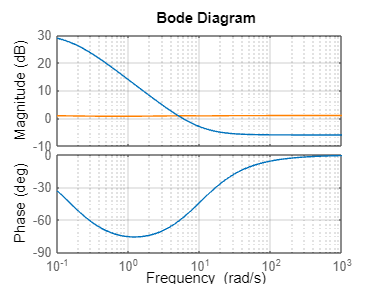


figure;
semilogx(omega,min_sv, 'Color', [1, 0.5, 0]);
hold on

% Plot the magnitude response of W1
bode(W1,omega);
grid on

%maximum singular values of inv(So)
max_sv = max(sigma(To,omega))

max_sv =     0.9655    0.9654    0.9654    0.9654    0.9653    0.9653    0.9652    0.9652    0.9651    0.9650    0.9649    0.9647    0.9646    0.9644    0.9642    0.9642    1.0137    1.1164    1.2238    1.3350    1.4489    1.5640    1.6786    1.7909    1.8984    1.9986    2.0888    2.1665    2.2291    2.2745    2.3013    2.3084    2.2958    2.2642    2.2148    2.1496    2.0710    1.9816    1.8842    1.7812    1.6753    1.5684    1.4624    1.3587    1.2584    1.1623    1.0711    0.9850    0.9042    0.8287


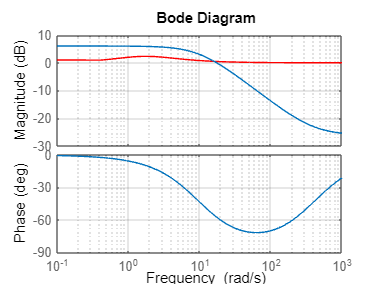


% Plot maximum singular values
figure;
semilogx(omega,max_sv, 'r');
hold on

% PLot the magnitude response of W1
bode(1/W3,omega);
grid on
hold off

**Comment**

minimum  singular value of $S^{-1}$  lie below the magnitude response of W1 for frequency which are less than **5.21 rad **but beyond this limit, minimum singular value of $S^{-1}$ is above the magnitude response of W1.

The maximum singular value of T lie below the magnitude  response of 1/W3 only for the frequencies which are less than **16.61 rad **otherwise not.

(ii) **Plot the transient responses of the uncertain closed-loop system.  Comment on the mutual interaction between the 2 channels. **

w1 = makeweight(0.1,20,10);
w2 = makeweight(0.2,25,10);
W = blkdiag(w1,w2);
D1 = ultidyn('Delta_1', [1 1]);
D2 = ultidyn('Delta_2', [1 1]);
Delta = blkdiag(D1,D2);
G = Gnom*(eye(2) + Delta*W); 
looptransfer = loopsens(G,Kh);
Ti = looptransfer.Ti;
[PeakNorm,freq] = norm(W*Ti.Nominal,'inf')

PeakNorm = 0.4925

freq = 1.9988

norm_Delta = norm(Delta, 'inf')

norm_Delta = 0

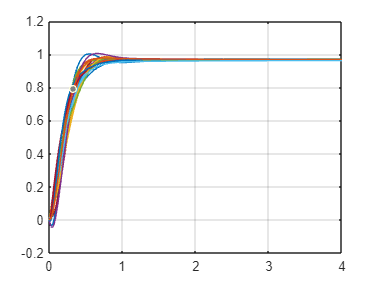

tfin = 4;
nsample = 30;
To = looptransfer.To;
[To30,samples] =usample(To,nsample);
time = 0:tfin/500:tfin;
nstep = size(time,2);
ref1(1:nstep) = 1.0;
ref2(1:nstep) = 0.0;
ref = [ref1' ref2'];
figure;
% subplot(2,2,1)
hold off
for i = 1:nsample
    [y,t] =lsim(To30(1:2,1:2,i),ref,time);
    plot(t,y(:,1));
    hold on;
end
grid on

From my examination it is clear that the system achieves stability, with each channel arriving at an equalized endpoint. This uniformity might reflect identical setpoints. Interestingly, one channel initially overshoots which is a sign of less damping, yet eventually mirrors the calmer channel's steady state, suggesting distinct underlying characteristics. The restrained interaction between channels points to a possibly decoupled design, an observation that aligns with the principles of robust $\( H_{\infty} \)$ control methodologies. This is a positive indicator that the system is engineered to maintain reliable performance, effectively balancing dynamic behavior and uncertainty.

## Robust Performance

(i). Analyze the robust performance of the closed loop system

WS = blkdiag(W1,W1);
WT = blkdiag(W3,W3);
systemnames = ' G Kh WS WT '; 
inputvar = '[ ref{2}; dist{2} ]';
outputvar = '[ WS; WT ]';
input_to_G = '[ Kh ]';
input_to_K = '[ ref-G-dist ]';
input_to_WS = '[ ref-G-dist ]';
input_to_WT = '[ G + dist]';
clp = sysic;
norm(clp.Nom,'inf')

ans = 47.1418

omega = logspace(-1,2,200);
clp_g = ufrd(clp,omega);
opt = robopt('Display','on');
[perfmarg,perfmargunc,report,info] = robustperf(clp_g,opt)

Points completed: 200/200
ROBUSTSTAB Sensitivity calculations are beginning.
      Uncertain element Delta_1...
      Uncertain element Delta_2...


perfmarg = struct with fields:
           LowerBound: 0.0255
           UpperBound: 0.0255
    CriticalFrequency: 0.1000


perfmargunc = struct with fields:
    Delta_1: [1×1 ss]
    Delta_2: [1×1 ss]


report = 6×113 char array
    'Uncertain system does not achieve performance robustness to modeled uncertainty.                                 '
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 2.55% of the modeled uncertainty.'
    ' -- A model uncertainty of 2.55% can lead to input/output gain of 39.2 at 0.1 rad/seconds.                       '
    ' -- Sensitivity with respect to each uncertain element is:                                                       '
    '      0% for Delta_1. Increasing Delta_1 by 25% decreases the margin by 0%.                                      '
    '      0% for Delta_2. Increasing Delta_2 by 25% decreases the margin by 0%.                                      '


info = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [200×1 double]
    BadUncertainValues: [200×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]


## Mixed Sensitivity Design with Output Multiplicative Uncertainty

nums = {12 -0.05; 0.1 [1 0]};
dens = {[0.2 1] [0.1 1]; [0.3 1] [0.7 -1]};
Gnom = tf(nums,dens);


## POLES AND ZERO

disp('Poles: ')

Poles: 


pole(Gnom)

ans =    -5.0000
   -3.3333
  -10.0000
    1.4286



disp('Zeros: ')

Zeros: 


tzero(Gnom)

ans =   -10.0017
    0.0004
   -3.3340


## TFM to SS

sysss = ss(Gnom)

sysss =
 
  A = 
           x1      x2      x3      x4
   x1      -5       0       0       0
   x2       0  -3.333       0       0
   x3       0       0     -10       0
   x4       0       0       0   1.429
 
  B = 
        u1   u2
   x1    8    0
   x2  0.5    0
   x3    0  0.5
   x4    0    2
 
  C = 
           x1      x2      x3      x4
   y1     7.5       0      -1       0
   y2       0  0.6667       0    1.02
 
  D = 
          u1     u2
   y1      0      0
   y2      0  1.429
 
Continuous-time state-space model.


## MINIMAL REALIZATION

Ctrb = ctrb(sysss.A, sysss.B);
% Check the rank of the controllability matrix
rank_Ctrb = rank(Ctrb)

rank_Ctrb = 4


% Determine if the system is controllable
if rank_Ctrb == size(sysss.A, 1)
    disp('The system is controllable.');
else
    disp('The system is not controllable.');
end

The system is controllable.



Obsv_mat = obsv(sysss);
rank_obs = rank(Obsv_mat)

rank_obs = 4


% Determine if the system is controllable
if rank_obs == size(sysss.A, 1)
    disp('The system is observable.');
else
    disp('The system is not observable.');
end

The system is observable.


## SINGULAR VALUE OF Gnom for all frequencies

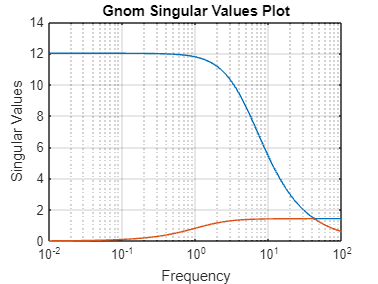

f_range = logspace(-2, 2, 100);  % Frequency range
sv = sigma(Gnom, f_range);
figure;
semilogx(f_range, sv);
xlabel('Frequency');
ylabel('Singular Values');
title('Gnom Singular Values Plot');
grid on

% maximum singular value for all frequencies
max_sv = max(sv);
fprintf('Max singular value: %.2f\n', max_sv);

Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 12.00
Max singular value: 11.99
Max singular value: 11.99
Max singular value: 11.99
Max singular value: 11.99
Max singular value: 11.99
Max singular value: 11.98
Max singular value: 11.98
Max singular value: 11.98
Max singular

## MIXED SENSITIVITY PROBLEM

s = tf('s');
Gnom = [13.8/(0.16*s+1) -0.05/(0.1*s + 1); 0.1/(0.3*s+1) (4.25*s)/(0.84*s-1)]

Gnom =
 
  From input 1 to output...
          13.8
   1:  ----------
       0.16 s + 1
 
          0.1
   2:  ---------
       0.3 s + 1
 
  From input 2 to output...
         -0.05
   1:  ---------
       0.1 s + 1
 
         4.25 s
   2:  ----------
       0.84 s - 1
 
Continuous-time transfer function.
Model Properties



% weights
W1 = (s+10)/(2*s+0.3);
W2 = []; 
W3 = (s+10)/(0.05*s+20);

## OPTIMAL H infinity controller

% H-infinity optimal controller
[Kh,cl,gamma,info] = mixsyn(Gnom,W1,W2,W3);
Kh

Kh =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1       -0.15  -9.343e-20  -1.146e-19  -2.424e-20  -3.554e-15   3.794e-20   2.221e-16  -4.852e-19
   x2  -2.954e-15       -0.15   1.144e-17   1.421e-14   1.048e-14  -1.668e-13  -6.076e-16    2.46e-12
   x3    3.56e-18  -2.119e-16        -400   2.429e-14         690   6.831e-16         -64  -4.881e-15
   x4     0.02079       1.055    -0.01427      -74.94    -0.05133       7.599    0.002255      -45.98
   x5       4.313     0.02897        86.4     0.08946      -170.9    -0.01855       15.05     0.07638
   x6      0.2696     0.00181         5.4    0.005591      -10.29      -3.334      0.9409    0.004774
   x7   3.264e-05    0.001598  -2.218e-05      0.5056  -7.461e-05    -0.05405         -10     -0.3694
   x8  -0.0005867     0.04908   0.0001223      -2.871   -0.006555     -0.3538   0.0006802      0.6965
 
  B = 
               u1          u2
   x1           2   -4.58e-21

cl

cl =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16
   x1        -0.15           0           0           0      -21.56           0           2           0           0           0           0           0           0           0           0           0
   x2            0       -0.15           0           0           0      -1.333           0      -6.023  -0.0006605    -0.03233    0.000449      -10.23     0.00151       1.094  -6.044e-05       7.475
   x3            0           0        -400           0         690           0         -64           0           0           0           0           0           0           0           0           0
   x4            0           0           0        -400           0       42.67           0       192.7     0.02114       1.035    -0.01437       327.4    -0.04832         -35    0.001934    

gamma

gamma = 33.3361

(ii) Analyse the sensitivity and complementary sensitivity functions  with the aid of the following commands. Does the minimum  singular value of $S^{-1}$  lie below the magnitude response of W1 and  the maximum singular value of T lie below the magnitude  response of 1/W3 ?

looptransfer = loopsens(Gnom,Kh)

looptransfer = struct with fields:
        Si: [2×2 ss]
        Ti: [2×2 ss]
        Li: [2×2 ss]
        So: [2×2 ss]
        To: [2×2 ss]
        Lo: [2×2 ss]
       PSi: [2×2 ss]
       CSo: [2×2 ss]
     Poles: [12×1 double]
    Stable: 1


Lo = looptransfer.Lo;
To = looptransfer.To

To =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1        -6.25           0           0           0      -4.313    -0.02897       -86.4    -0.08946       164.7     0.01855      -15.05    -0.07638
   x2            0      -3.333           0           0     -0.2696    -0.00181        -5.4   -0.005591       10.29    0.001159     -0.9409   -0.004774
   x3            0           0         -10           0  -3.264e-05   -0.001598   2.218e-05     -0.5056   7.461e-05     0.05405  -2.986e-06      0.3694
   x4            0           0           0        1.19  -0.0001305    -0.00639   8.874e-05      -2.022   0.0002985      0.2162  -1.194e-05       1.477
   x5        21.56  -3.053e-21          -2  -1.379e-20       -0.15  -9.336e-20  -1.146e-19  -8.081e-22  -3.554e-15   3.543e-20   2.221e-16  -5.024e-19
   x6    4.673e-18       1.333  -4.334e-19       6.023  -0.0006605     -0.1823  

So = looptransfer.So

So =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1        -6.25           0           0           0      -4.313    -0.02897       -86.4    -0.08946       164.7     0.01855      -15.05    -0.07638
   x2            0      -3.333           0           0     -0.2696    -0.00181        -5.4   -0.005591       10.29    0.001159     -0.9409   -0.004774
   x3            0           0         -10           0  -3.264e-05   -0.001598   2.218e-05     -0.5056   7.461e-05     0.05405  -2.986e-06      0.3694
   x4            0           0           0        1.19  -0.0001305    -0.00639   8.874e-05      -2.022   0.0002985      0.2162  -1.194e-05       1.477
   x5        21.56  -3.053e-21          -2  -1.379e-20       -0.15  -9.336e-20  -1.146e-19  -8.081e-22  -3.554e-15   3.543e-20   2.221e-16  -5.024e-19
   x6    4.673e-18       1.333  -4.334e-19       6.023  -0.0006605     -0.1823  

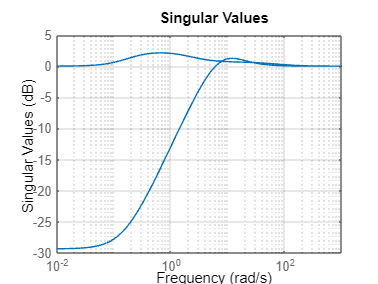

I = eye(size(Lo));
figure(2)
omega = logspace(-1,3,100);
sigma(So), grid on

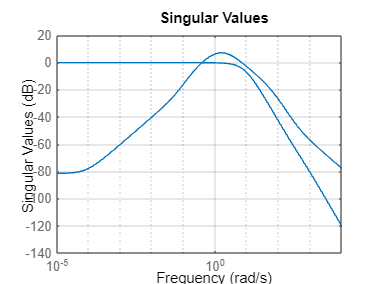

sigma(To), grid on


% minimum singular values of 1/So
min_sv = min(sigma(inv(So),omega))

min_sv =     0.9317    0.9223    0.9122    0.9016    0.8906    0.8794    0.8683    0.8573    0.8468    0.8368    0.8275    0.8190    0.8113    0.8046    0.7988    0.7939    0.7899    0.7867    0.7844    0.7830    0.7823    0.7823    0.7831    0.7847    0.7870    0.7901    0.7939    0.7984    0.8037    0.8095    0.8160    0.8230    0.8304    0.8381    0.8458    0.8536    0.8612    0.8686    0.8755    0.8820    0.8880    0.8934    0.8983    0.9027    0.9065    0.9098    0.9127    0.9056    0.8874    0.8749


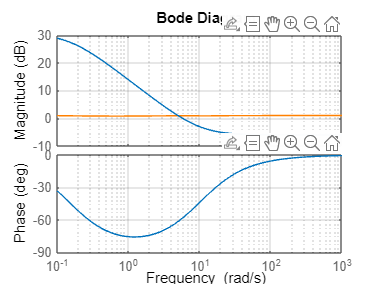


figure;
semilogx(omega,min_sv, 'Color', [1, 0.5, 0]);
hold on

% Plot the magnitude response of W1
bode(W1,omega);
grid on

%maximum singular values of inv(So)
max_sv = max(sigma(To,omega))

max_sv =     0.9658    0.9657    0.9657    0.9657    0.9656    0.9656    0.9655    0.9655    0.9654    0.9653    0.9652    0.9650    0.9649    0.9647    0.9649    1.0327    1.1333    1.2381    1.3459    1.4557    1.5658    1.6746    1.7800    1.8798    1.9713    2.0523    2.1201    2.1728    2.2086    2.2263    2.2254    2.2060    2.1691    2.1160    2.0487    1.9695    1.8810    1.7856    1.6858    1.5836    1.4811    1.3798    1.2810    1.1857    1.0947    1.0083    0.9269    0.8507    0.7795    0.7132


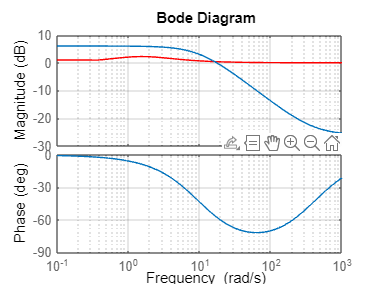


% Plot maximum singular values
figure;
semilogx(omega,max_sv, 'r');
hold on

% PLot the magnitude response of W1
bode(1/W3,omega);
grid on
hold off

**Comment**

minimum  singular value of $S^{-1}$  lie below the magnitude response of W1 for frequency which are less than **5.007 rad **but beyond this limit, minimum singular value of $S^{-1}$ is above the magnitude response of W1.

The maximum singular value of T lie below the magnitude  response of 1/W3 only for the frequencies which are less than **16.312 rad **otherwise not.

(ii) **Plot the transient responses of the uncertain closed-loop system.  Comment on the mutual interaction between the 2 channels. **

w1 = makeweight(0.1,20,10);
w2 = makeweight(0.2,25,10);
W = blkdiag(w1,w2);
D1 = ultidyn('Delta_1', [1 1]);
D2 = ultidyn('Delta_2', [1 1]);
Delta = blkdiag(D1,D2);
G = Gnom*(eye(2) + Delta*W); 
looptransfer = loopsens(G,Kh);
Ti = looptransfer.Ti;
[PeakNorm,freq] = norm(W*Ti.Nominal,'inf')

PeakNorm = 0.4681

freq = 1.7128

norm_Delta = norm(Delta, 'inf')

norm_Delta = 0

tfin = 4;
nsample = 30;
To = looptransfer.To;
[To30,samples] =usample(To,nsample);
time = 0:tfin/500:tfin;
nstep = size(time,2);
ref1(1:nstep) = 1.0;
ref2(1:nstep) = 0.0;
ref = [ref1' ref2'];
figure;
% subplot(2,2,1)
hold off
for i = 1:nsample
    [y,t] =lsim(To30(1:2,1:2,i),ref,time);
    plot(t,y(:,1));
    hold on;
end

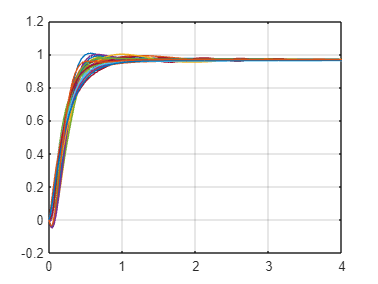

grid on

From my examination it is clear that the system achieves stability, with each channel arriving at an equalized endpoint. This uniformity might reflect identical setpoints. Interestingly, one channel initially overshoots which is a sign of less damping, yet eventually mirrors the calmer channel's steady state, suggesting distinct underlying characteristics. The restrained interaction between channels points to a possibly decoupled design, an observation that aligns with the principles of robust $\( H_{\infty} \)$ control methodologies. This is a positive indicator that the system is engineered to maintain reliable performance, effectively balancing dynamic behavior and uncertainty.

## Robust Performance

(i). Analyze the robust performance of the closed loop system

WS = blkdiag(W1,W1);
WT = blkdiag(W3,W3);
systemnames = ' G Kh WS WT '; 
inputvar = '[ ref{2}; dist{2} ]';
outputvar = '[ WS; WT ]';
input_to_G = '[ Kh ]';
input_to_K = '[ ref-G-dist ]';
input_to_WS = '[ ref-G-dist ]';
input_to_WT = '[ G + dist]';
clp = sysic;
norm(clp.Nom,'inf')

ans = 47.1418

omega = logspace(-1,2,200);
clp_g = ufrd(clp,omega);
opt = robopt('Display','on');
[perfmarg,perfmargunc,report,info] = robustperf(clp_g,opt)

Points completed: 200/200
ROBUSTSTAB Sensitivity calculations are beginning.
      Uncertain element Delta_1...
      Uncertain element Delta_2...


perfmarg = struct with fields:
           LowerBound: 0.0255
           UpperBound: 0.0255
    CriticalFrequency: 0.1000


perfmargunc = struct with fields:
    Delta_1: [1×1 ss]
    Delta_2: [1×1 ss]


report = 6×113 char array
    'Uncertain system does not achieve performance robustness to modeled uncertainty.                                 '
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 2.55% of the modeled uncertainty.'
    ' -- A model uncertainty of 2.55% can lead to input/output gain of 39.2 at 0.1 rad/seconds.                       '
    ' -- Sensitivity with respect to each uncertain element is:                                                       '
    '      0% for Delta_1. Increasing Delta_1 by 25% decreases the margin by 0%.                                      '
    '      0% for Delta_2. Increasing Delta_2 by 25% decreases the margin by 0%.                                      '


info = struct with fields:
           Sensitivity: [1×1 struct]
             Frequency: [200×1 double]
    BadUncertainValues: [200×1 struct]
             MussvBnds: [1×2 frd]
             MussvInfo: [1×1 struct]
